# **各向异性的静磁隐形装置**

**        由于隐形是一种特殊的幻觉。在**[**上一小节**](matlab:open('./D6_Anisotropic_Static_Magnetic_Illusion_Device.mlx'))**的基础上，将各向异性的静磁幻觉装置中的幻觉物体用磁导率等于**$\mu_3 =1$**的背景代替即可得到隐形装置。**

**        通过对拉普拉斯方程**$\nabla^2 \phi_m =0$**进行分离变量，并匹配边界条件，计算得到**$R_1 <r<R_2$**隐形套层区域内的磁导率分布可以表达为：**


$$\mu_2 =\sqrt{\mu_{2r} \mu_{2\theta } }=\frac{n\left(\mu_1 -\mu_0 \right)}{2}\pm \frac{\sqrt{n^2 {\left(\mu_1 -\mu_0 \right)}^2 +4\mu_0 \mu_1 }}{2}$$


**        其中，**$n=\frac{{\left(R_2 /R_1 \right)}^{2l} +1}{{\left(R_2 /R_1 \right)}^{2l} -1}$**,**$l=\sqrt{\frac{\mu_{2\theta } }{\mu_{2r} }}$

**        仿真中设**$R_1 =5\textrm{mm}$**，**$R_2 =10\textrm{mm}$**，**$\mu_0 =2$**，**$\mu_1 =\mu_3 =1$**。对各向异性的情况，设**$l=\sqrt{\mu_{2\theta } /\mu_{2r} }=2$**，计算可得**$\mu_2 =0\ldotp 9568526509$**、**$\mu_{2\theta } =1\ldotp 913705302$**，**$\mu_{2r} =0\ldotp 4784263255$**。**

**        在PDETool中对静磁隐形装置进行仿真，得到的结果如下图所示： **

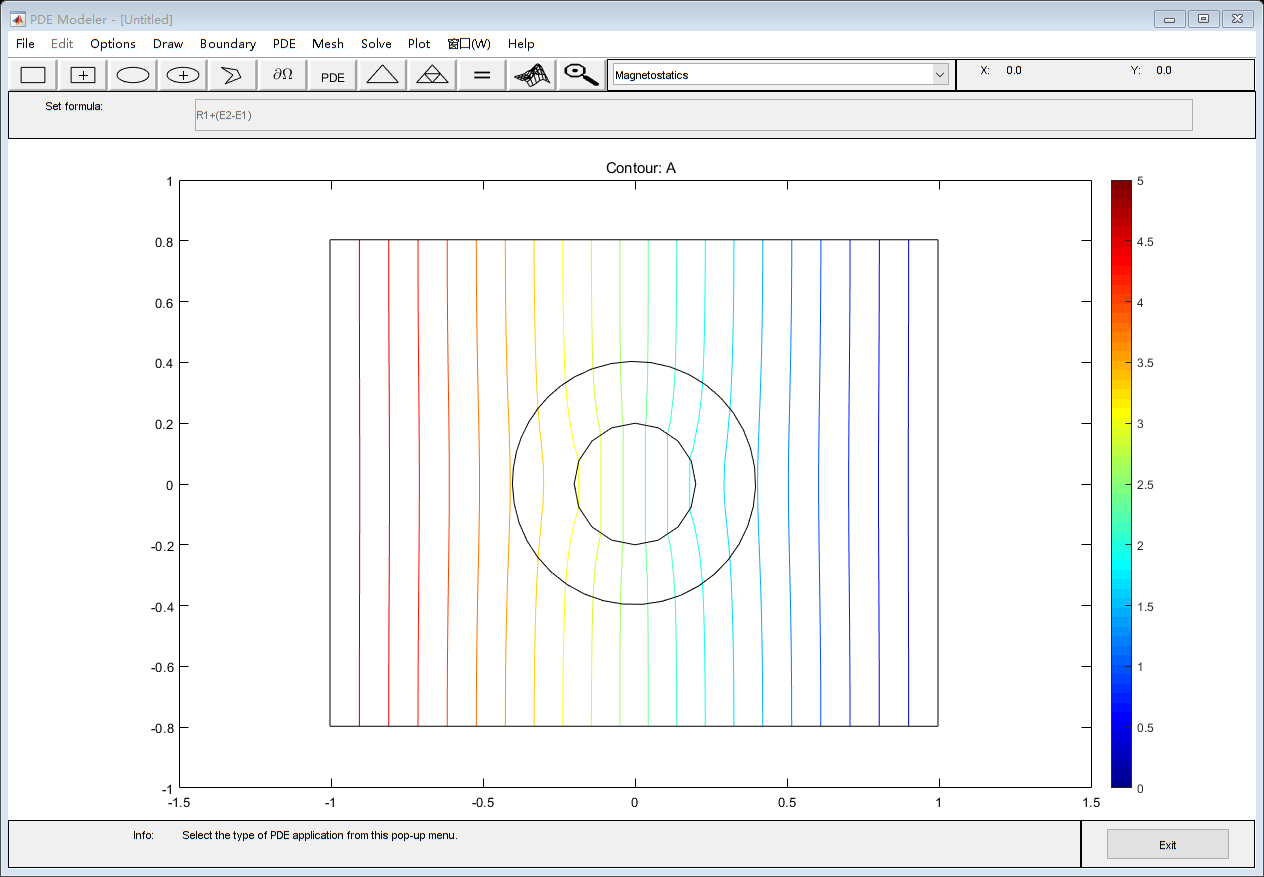

With_Invisibility_Cloak

function With_Invisibility_Cloak
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',6);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1.0032894736842097 0.99671052631579027 0.80328947368421066 -0.79671052631578942],'R1');
    pdeellip(0,0,0.20000000000000001,0.20000000000000001,...
    0,'E1');
    pdeellip(-0.0032894736842097316,0.0032894736842106198,0.40000000000000002,0.40000000000000002,...
    0,'E2');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1+(E2-E1)')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1./(1)!1./(0.9568526509)!1./(2)',...
    '0.0!0.0!0.0',...
    '0!0!0',...
    '1.0!1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1!0.9568526509!2';...
    '0!0!0           '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1680','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 7 1 0 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end